# SIM.8. Proportional Integral Design

a = 3.6029;
b = 70.3494;
w = 2.7;
s_d = -a + w*1i;

phi_ULG = angle(b / (s_d + a));
phi_PI = -pi - phi_ULG;
z_PI = a + w/tan(phi_PI + angle(s_d))

z_PI = 5.6263


G_c = (s_d+z_PI)/s_d;
G_p = (b/(s_d+a));
K = abs(1/(G_c*G_p))

K = 0.0512

Gp = zpk([],-3.6029,70.3494) % define the plant TF as an object

Gp =
 
   70.349
  ---------
  (s+3.603)
 
Continuous-time zero/pole/gain model.
Model Properties


Gc = zpk(-5.6263, [0], 1) % define the compensator TF

Gc =
 
  (s+5.626)
  ---------
      s
 
Continuous-time zero/pole/gain model.
Model Properties


H = zpk([], [], 1); % define the sensor TF
K = 0.0512;

OLTF = Gc*Gp*H; % blocks in cascade
CLTF = feedback(K*Gc*Gp,H); % negative feedback loop: forward path K*Gc*Gp & feedback H

[y,tOut] = step(CLTF, 5); % unit step on CLTF
S = stepinfo(CLTF); % calculate step response info
T_s = S.SettlingTime;
OS = S.Overshoot;
fprintf('PD Controller:\n T_s=%f s\n OS=%f \n',T_s,OS)

PD Controller:
 T_s=1.078542 s
 OS=3.124585 


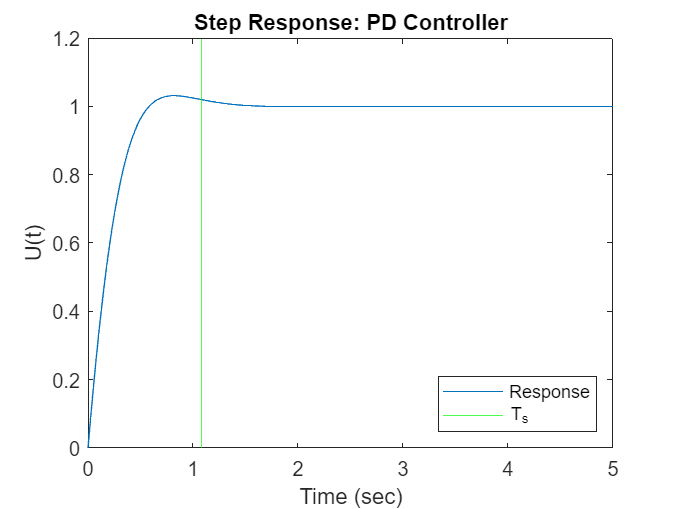


figure; clf;
plot(tOut, y)
xline(S.SettlingTime, 'g')
title("Step Response: PD Controller")
xlabel("Time (sec)")
ylabel("U(t)")
legend("Response", "T_s", "Location", "southeast")

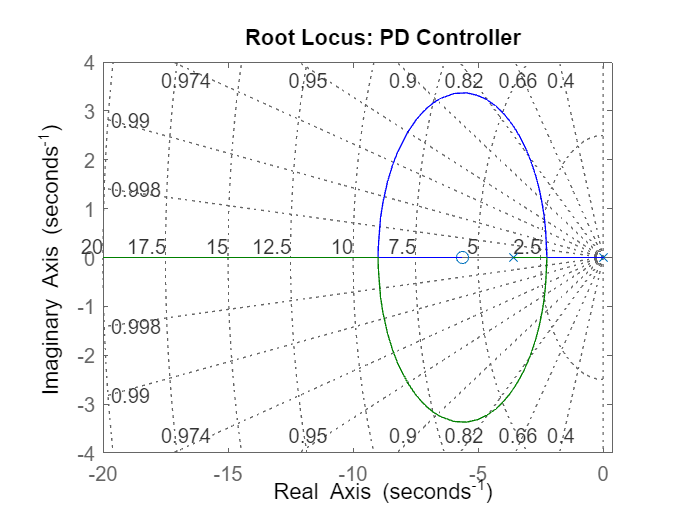


figure; clf;
rlocus(OLTF); % generate the RL for positive K
title("Root Locus: PD Controller")
sgrid; % overlay a grid in polar coordinates

axis; % adjust ranges along x and y axes